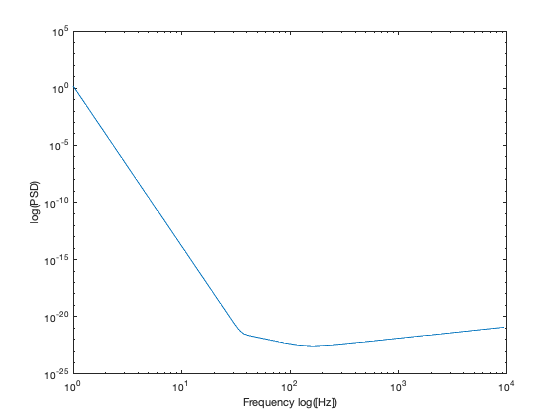

%Lab 8 part 2
%Luis Mario Bres Castro

%FIXME Modify code to use sampling frequency of 4096 Hz and max. freq. in filter design of 2048 Hz.

iLigofile=load('iLIGOSensitivity.txt', '-ascii');
freq=iLigofile(:,1)';
sqrtPSD=iLigofile(:,2)';

loglog(freq,sqrtPSD)
xlabel('Frequency log([Hz])')
ylabel('log(PSD)')

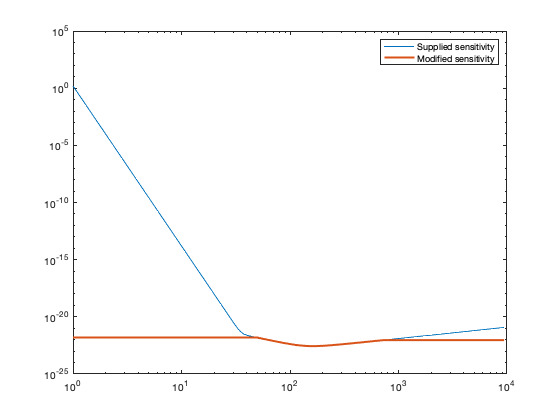

%Modifications
sampFreq = 6000; %Hz

% fsi=find(freq>=sampFreq/2)
% PSD_fsi=sqrtPSD(86);
f50=freq(42);
f50_ind=42;
Psd50=sqrtPSD(42);
f700=find(freq>=700);
freq(70);
f700_ind=70;
Psd700=sqrtPSD(70);


iLigofile(1,2)=sqrtPSD(42);
iLigofile(1:42,2)=Psd50;
iLigofile(70:end,2)=Psd700;



iLigofile(2:end+1,:) = iLigofile;
iLigofile(1,1)=0;
iLigofile(1,2)=Psd50;

%FIXME axes labels and title
%SDM compare with supplied curve
loglog(freq, sqrtPSD);

f=iLigofile(:,1)';
PSD=iLigofile(:,2)';
hold on
loglog(f,PSD, 'LineWidth',2.0);
%SDM Add legends
legend('Supplied sensitivity','Modified sensitivity');

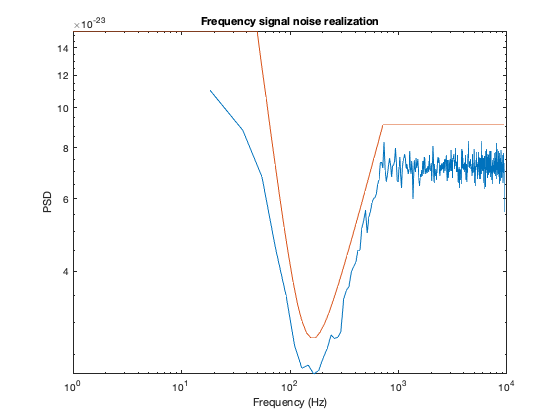

%Number of samples to generate
nSamples =10*sampFreq;
filtrOrd=600;

b = fir2(filtrOrd,f/f(end),PSD);
inNoise = randn(1,nSamples);
LigoNoise = sqrt(sampFreq)*fftfilt(b,inNoise);
%FIXME The sampling frequency you used is f(end)*2: see your filter design line
%SDM this was causing a shift in the location of the minimum of the PSD
%[pxx,fl]=pwelch(LigoNoise, 1000,[],[],sampFreq);
[pxx,fl]=pwelch(LigoNoise, 1000,[],[],2*f(end));
figure;
%FIXME loglog plot of sqrt(psd) to match supplied curve
loglog(fl,sqrt(pxx));
xlabel('Frequency (Hz)');
%SDM plot the supplied curve for comparison
hold on
loglog(f,PSD);
%FIXME What is the right title? What are you plotting? (Hint: Estimate of what?)
title('Frequency signal noise realization')
ylabel('PSD');

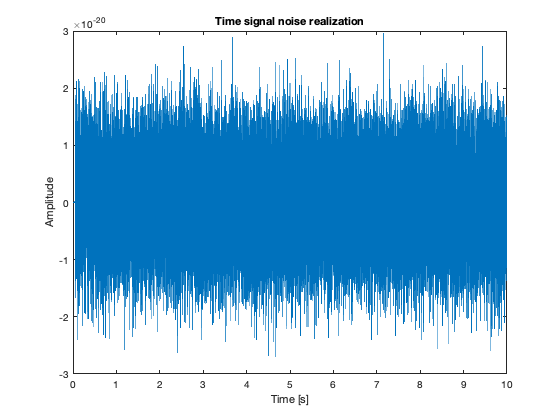

% Plot the colored noise realization
figure;
timeVec=(0:nSamples-1)/sampFreq;
plot(timeVec,LigoNoise);
xlabel('Time [s]')
ylabel('Amplitude')
%FIXME What is the right title? What are you plotting? (Hint: signal & noise together?)
title('Time signal noise realization')